Deflection in **z **and **y **at the **tip **versus time.

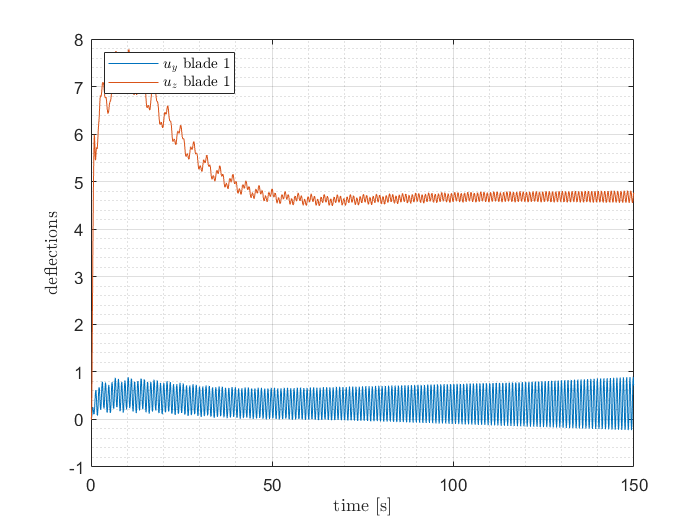

plot(time, u_blade_y(18,1:end-1), time, u_blade_z(18,1:end-1))
grid on; grid minor;
legend({'$u_y$ blade 1','$u_z$ blade 1'},"Interpreter","latex","Location","northwest")
xlabel('time [s]',"Interpreter","latex")
ylabel('deflections',"Interpreter","latex")

Deflection in **z (flapwise)**

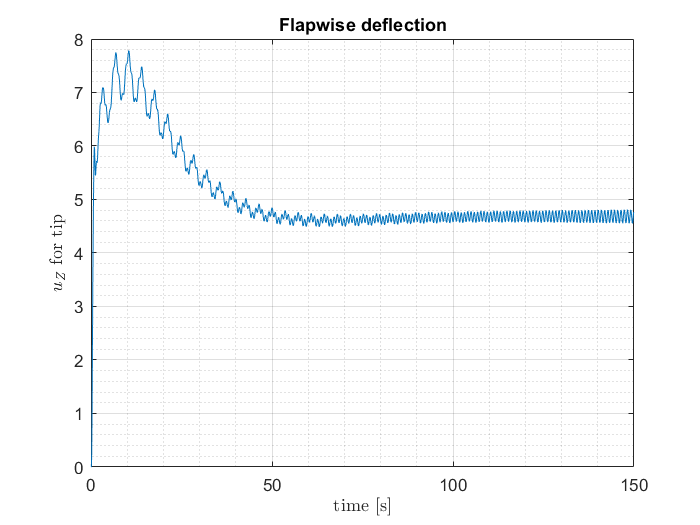

plot(time, u_blade_z(18,1:end-1));
ylabel('$u_Z$ for tip',"Interpreter","latex")
xlabel('time [s]',"Interpreter","latex")
title('Flapwise deflection')
grid on; grid minor;

Deflection in **y (edgewise)**

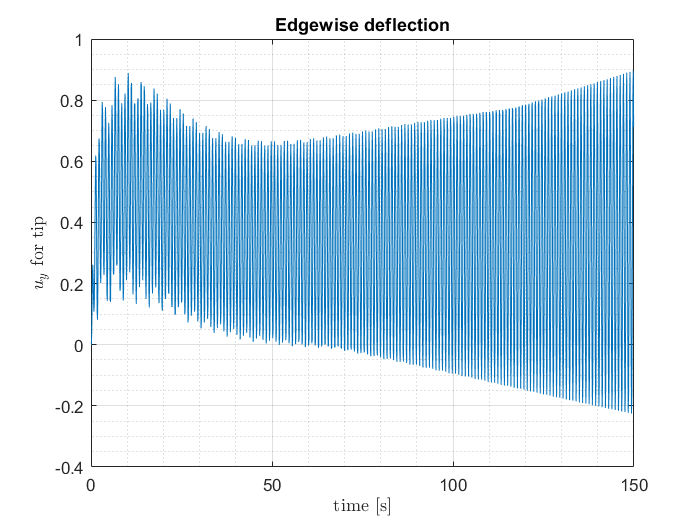

plot(time, u_blade_y(18,1:end-1));
ylabel('$u_y$ for tip',"Interpreter","latex")
xlabel('time [s]',"Interpreter","latex")
title('Edgewise deflection')
grid on; grid minor;

Tower position versus time. 

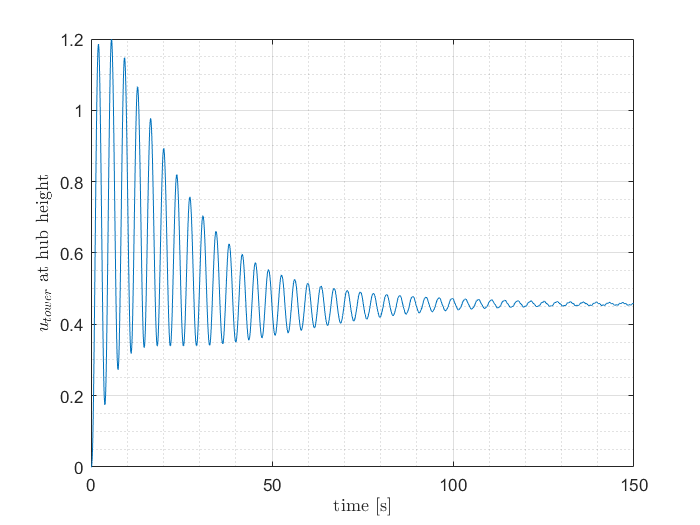

if DOF == 5
    plot(time, u_tow_spring(1:end-1))
    ylabel('$u_{tower}$ at hub height',"Interpreter","latex")
    xlabel('time [s]',"Interpreter","latex")
    grid on; grid minor;
end

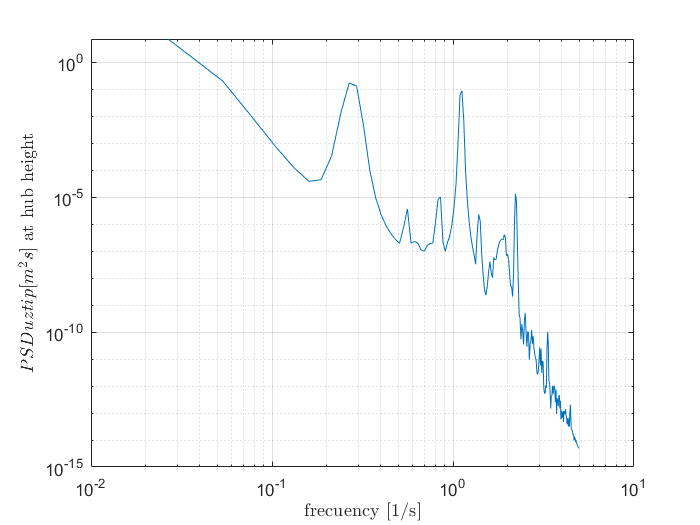

t_start_PSD = 0; % removes the first 70 seconds (transient)
t_end_PSD = Inf;
k_start_PSD = find(time>=t_start_PSD, 1, 'first');
k_end_PSD = find(time<=t_end_PSD, 1, 'last');
timesim_PSD = time(k_start_PSD:k_end_PSD); % transient removed
sampling_frequency = 1/dt;
nyquist_frequency = sampling_frequency/2;
n_parts_PSD = 4; %cuts the timeseries in 4 parts, this can be changed
window = hann(round(length(timesim_PSD)/n_parts_PSD), 'periodic');
noverlap = round(length(window)/2);
nperseg = length(window);
nfft = nperseg;
% Apply Welch's method
uztip = u_blade_z(18,:); 
uztipmean = mean( uztip(k_start_PSD:k_end_PSD) );
[pow_PSD_uztip, frequency_uytip] = pwelch( uztip(k_start_PSD:k_end_PSD) - uztipmean, window, ...
 noverlap, nfft, sampling_frequency, 'psd');
loglog(frequency_uytip, pow_PSD_uztip)

ylabel('$PSDuztip [m^2s] $ at hub height',"Interpreter","latex")
xlabel('frecuency [1/s]',"Interpreter","latex")

grid on; grid minor;